% 



RAW=struct();

warning('off','all');
RAW.Confirmed = import_git('time_series_covid19_confirmed_global.csv');
RAW.Deaths = import_git('time_series_covid19_deaths_global.csv');
RAW.Recovered = import_git('time_series_covid19_recovered_global.csv');
warning('on','all');

Categories=fieldnames(RAW);

StartDate = datetime(2020,01,22);
EndDate = StartDate+days(size(RAW.(Categories{1}),2)-5);

Selected_Countries=categorical({'US','United Kingdom','Germany','Switzerland','Canada','France','China',...
    'Singapore','Australia','India','Mauritius',...
    'Saudi Arabia','Korea, South','Italy'});


StartDate

StartDate = datetime
   22-Jan-2020



EndDate

EndDate = datetime
   06-Apr-2020 00:00:00


DailyIncrease_Confirmed


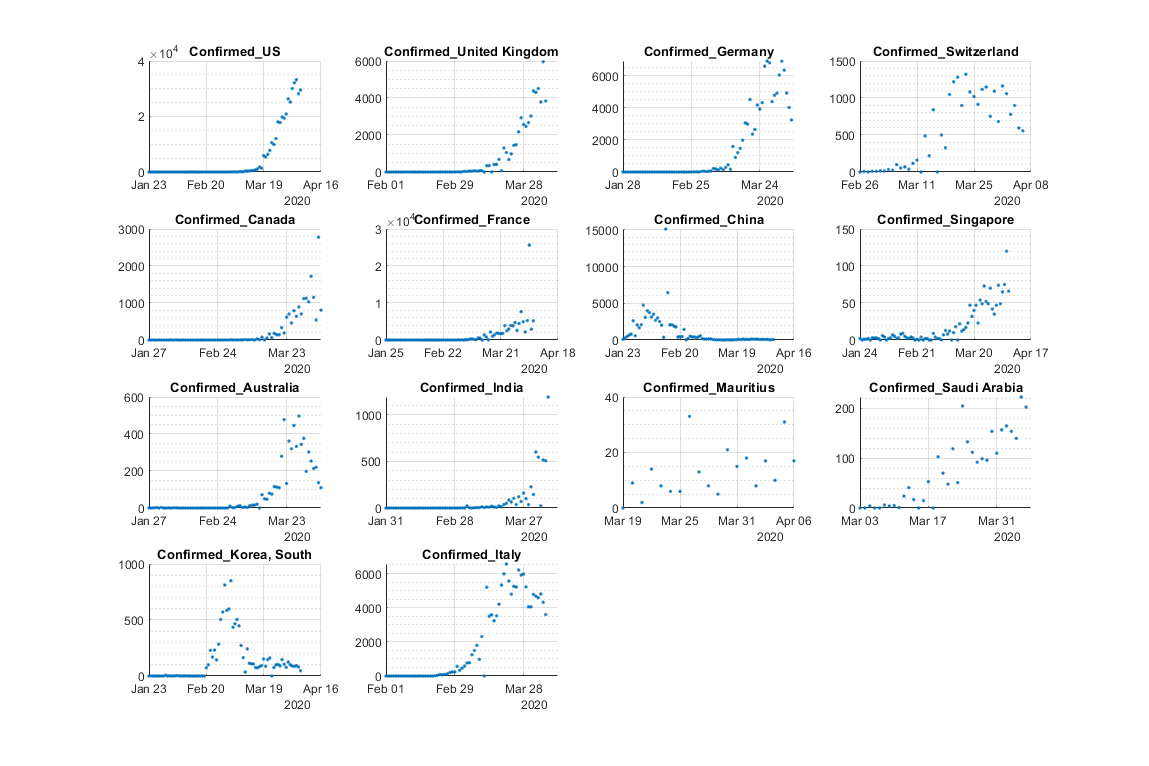

Grad of DailyIncrease_Confirmed


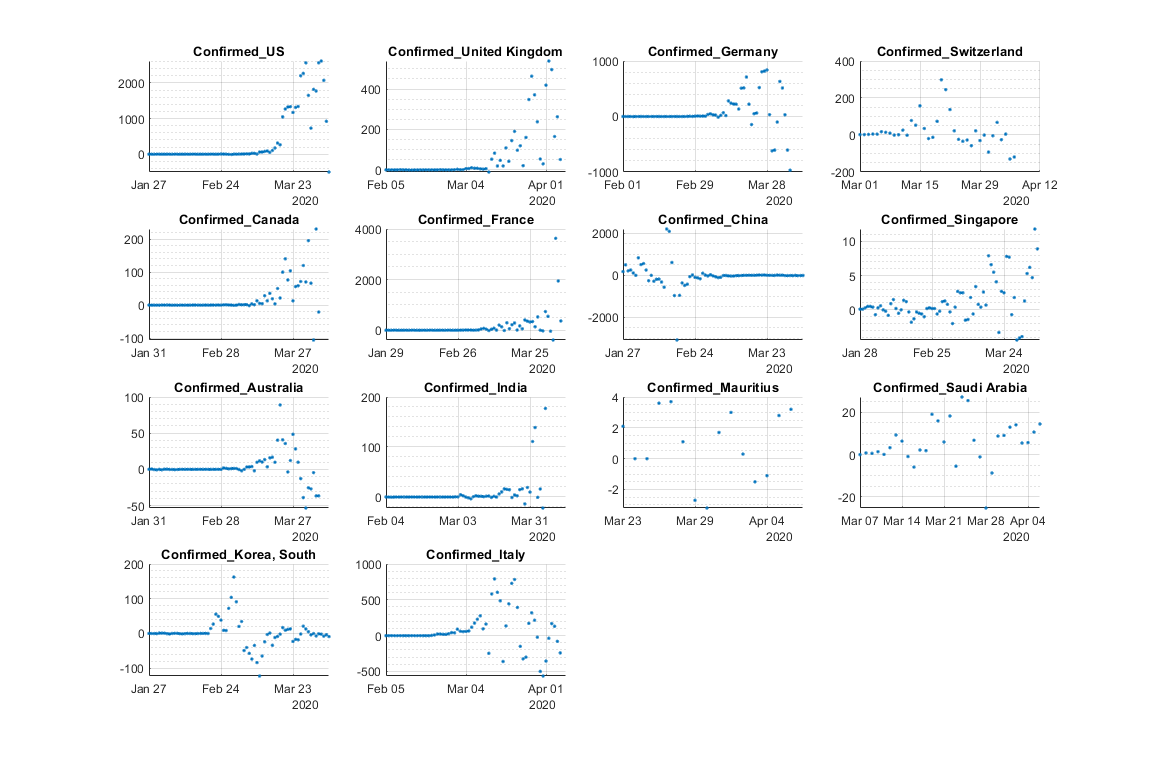

Confirmed


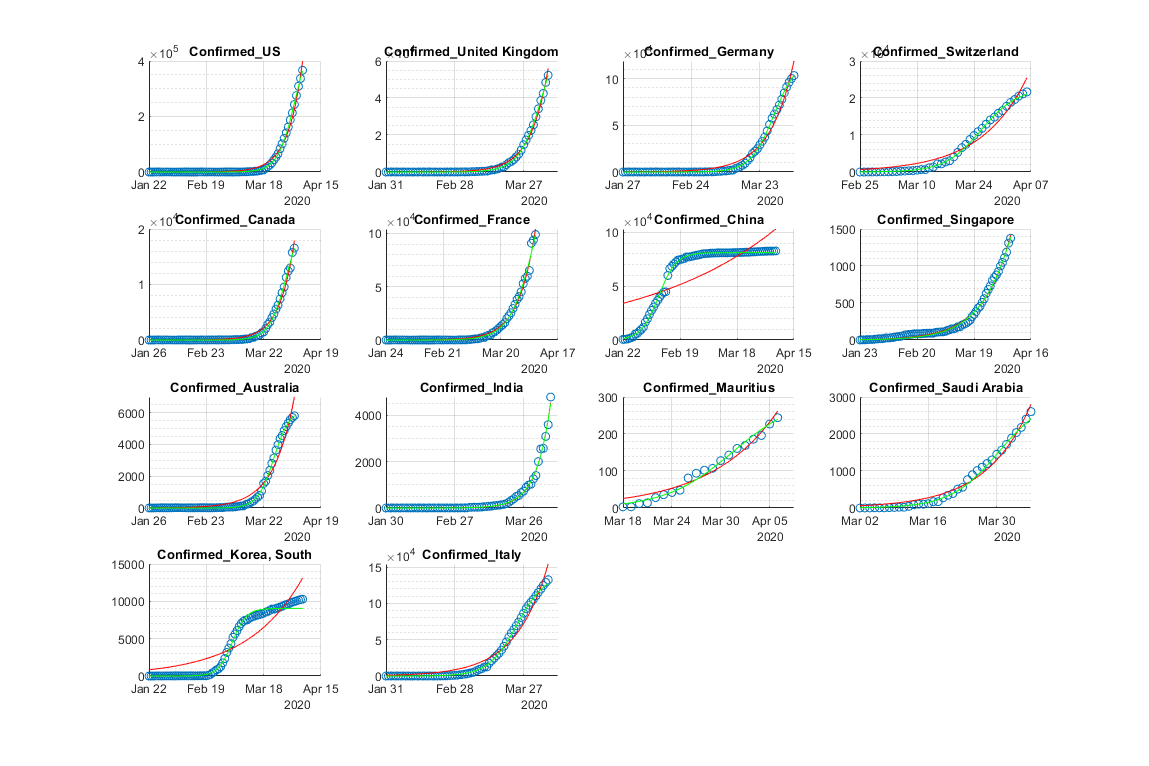

Log_Confirmed


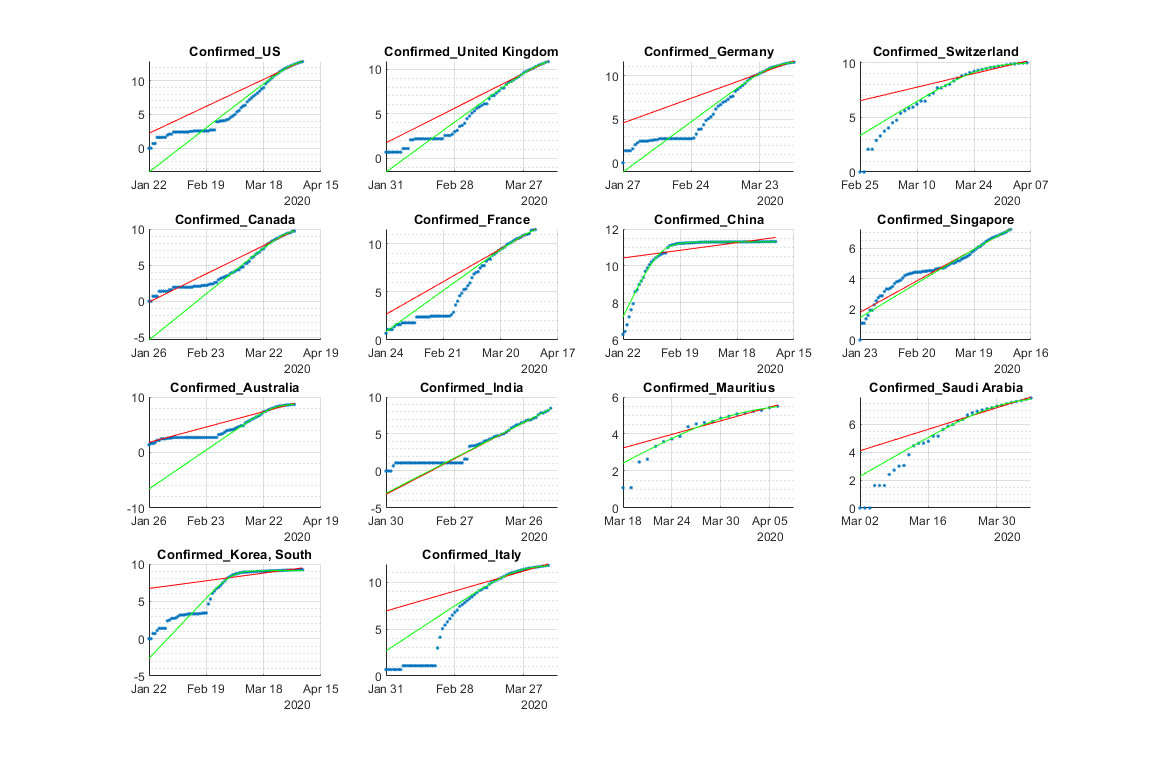

Gradient_Confirmed


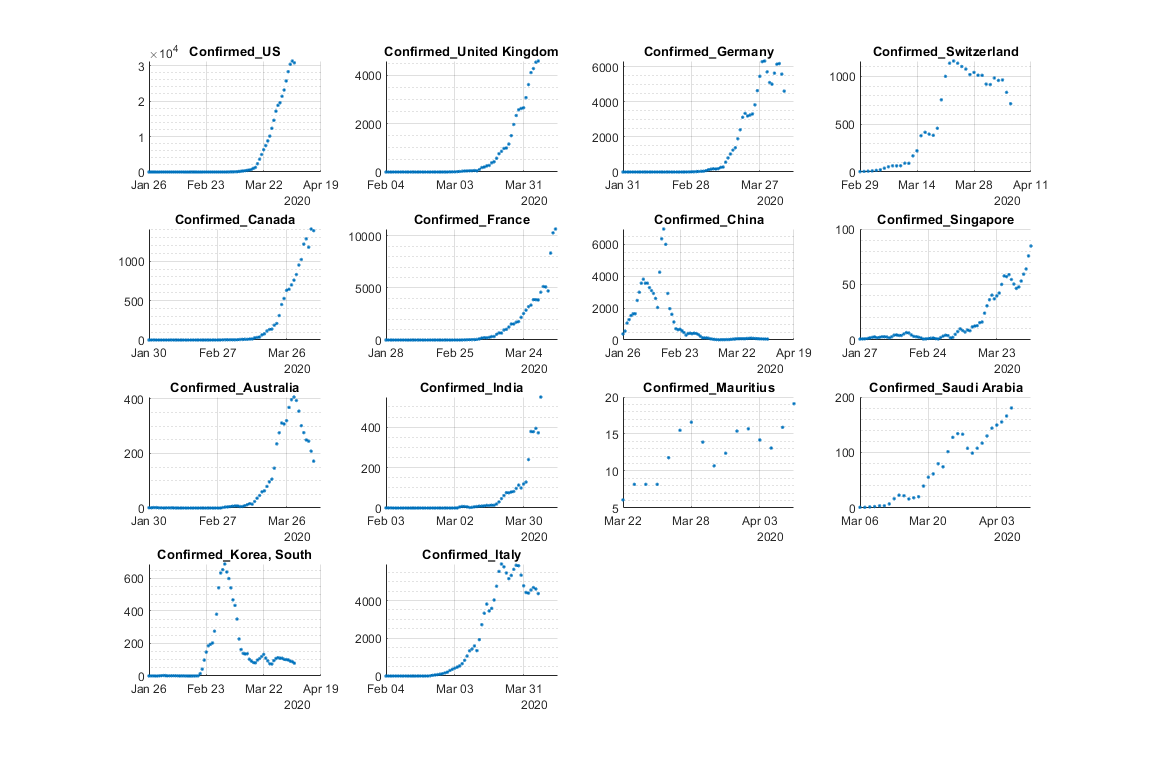

Goodness of Fit_Confirmed


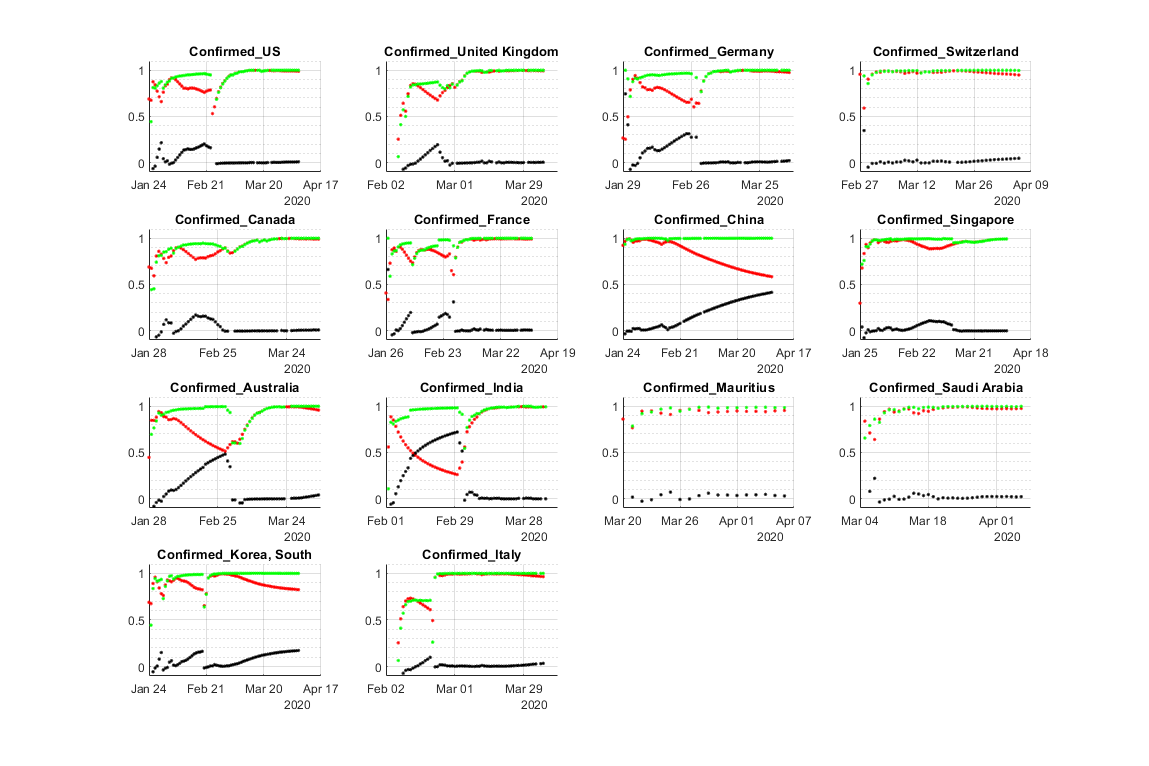


gradient_span=5; %days

CountrywiseData=struct();
for category_count=1:size(Categories,1)
    plot_titles=cell(size(Selected_Countries,2),1);
    for country_count=1:size(Selected_Countries,2)
        RAW.(Categories{category_count}).Country_Region=categorical(RAW.(Categories{category_count}).Country_Region);
        Idn=RAW.(Categories{category_count}).Country_Region==Selected_Countries(country_count);
        temp=RAW.(Categories{category_count}){Idn,(5:end)};
        CountrywiseData.(Categories{category_count})(country_count,:)=sum(temp,1);
        plot_titles{country_count,1}=[char(Categories{category_count}),'_',char(Selected_Countries(country_count))];
    end
    
    fig_title=char(Categories{category_count});
    SimpleScatter(StartDate,CountrywiseData.(Categories{category_count}),fig_title,plot_titles,gradient_span)
end